# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Newstru\Newstru1\RawData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                                  % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Newstru\Newstru1\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Block.Start   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {12};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)

## 2. PreProcessing Steps

Deci.PP.HBP        = 1;                                                                          % Scalar,High-bandpass filter, in Hz.
Deci.PP.Detrend = 1;
Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []   ;    
Deci.Art.RejectNans = 1;
Deci.Art.crittoilim = [-.5 1.5]; 

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.Locks         = [1 2 3];                                                          % Which Lock to Analyze        
Deci.Analysis.LocksTitle    = {'Stim Onset','Response Onset','Fdb Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.DownSample    = 500;                                              % Downsample Pre-Analysis
% Deci.Analysis.Conditions    = {[20 31 51] [21 31 51] [23 31 51] [24 31 51] [20 31 52] [21 31 52] [23 31 52] [24 31 52] ...
%                                [20 32 51] [21 32 51] [23 32 51] [24 32 51] [20 32 52] [21 32 52] [23 32 52] [24 32 52]};
% Deci.Analysis.CondTitle     = {'Opt AB Corr' 'Opt CD Corr' 'Opt EF Corr' 'Opt GH Corr' ...
%                                'Opt AB Inc'  'Opt CD Inc' 'Opt EF Inc' 'Opt GH Inc' ...
%                                'Wst AB Corr' 'Wst CD Corr' 'Wst EF Corr' 'Wst GH Corr' ...
%                                'Wst AB Inc'  'Wst CD Inc' 'Wst EF Inc' 'Wst GH Inc'}; 

Deci.Analysis.Conditions    = {[20] [21] [23] [24]};
Deci.Analysis.CondTitle     = {'AB' 'CD' 'EF' 'GH'};                                               
Deci.Analysis.Version = ['C:\Users\User\Desktop\John\Newstru\Newstru1\' 'Processed_QLLearning'];

#### Time-Frequency Analysis

Deci.Analysis.Freq.do            = true;
Deci_Wavelet;

#### Cross-Frequency Coupling

Deci.Analysis.CFC.do = false;
Deci.Analysis.CFC.chanlow =  {'FCz'};
Deci.Analysis.CFC.chanhigh = {'CP3'};
Deci.Analysis.CFC.latencyhigh = [-.2 1]; %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-.2 1];
Deci.Analysis.CFC.freqhigh = 'theta';
Deci.Analysis.CFC.freqlow = 'beta';

Deci.Analysis.CFC.timebin = 6;
Deci.Analysis.CFC.methods = {'mi' 'plv'};  % can only currently handle '' or 'mi'(pac)
Deci.Plot.CFC.errorbars = true ;

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];

Extra

Deci.Analysis.Extra.QL.States = [20 21 23 24];
Deci.Analysis.Extra.QL.Actions = [31 32];
Deci.Analysis.Extra.QL.Reward  = [51 52];
Deci.Analysis.Extra.QL.Value  = {[20 10] [10 0] [0 -10] [-10 20]};

Deci.Analysis.Extra.do = false;
Deci.Analysis.Extra.list = [true];
Deci.Analysis.Extra.Functions = {'QL'};
Deci.Analysis.Extra.Params = {{Deci.Analysis.Extra.QL}};

## 5. Plotting

Deci.Plot.Version = ['C:\Users\User\Desktop\John\Newstru\Newstru1\' 'Processed_QLLearning'];
Deci.Plot.Lock = 'Fdb Onset';
Deci.Plot.BslRef = 'Fdb Onset';
Deci.Plot.GrandAverage = true;
Deci.Plot.FreqYScale = 'linear';


#### Conditions

QLTrialsPlot

#### Statistics

Deci.Plot.Stat.do = true;
Deci.Plot.Stat.Type = 'Anova/T-test';
Deci.Plot.Stat.alpha = .05;
Deci.Plot.Stat.fdr = false;
Deci.Plot.Stat.FPlots =  false;

#### Time-Frequency

Deci.Plot.Freq.Foi     = [4 8];                   % Frequency of Interest
Deci.Plot.Freq.Toi     = [0 .5];                   % Time of Interest
Deci.Plot.Freq.Channel = ['Reinhart-All'];                   % Channel of Interest
Deci.Plot.Freq.Type    = 'TotalPower';                   % Use 'TotalPower','ITPC' or 'EvokedPower' (Currently Unavailable)
Deci.Plot.Freq.Bsl     = [-.5 -.2];                             % Baseline Correction Time
Deci.Plot.Freq.Topo    =true;
Deci.Plot.Freq.Square  =false;
Deci.Plot.Freq.Wire    =false;
Deci.Plot.Freq.Bar    =false;

**CFC**

%Currently Unavailable
Deci.Plot.CFC.Topo = true;
Deci.Plot.CFC.Square = true;
Deci.Plot.CFC.Hist = true;
Deci.Plot.CFC.Wire = true;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest

**ERP**

Deci.Plot.ERP.Toi = [0 .8];
Deci.Plot.ERP.Channel = {'FCz'};
Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.ERP.Topo =true;
Deci.Plot.ERP.Wire =true;

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Figure = [true false];
Deci.Plot.Behv.Acc.Total = {{[1:16] [1:16]} {[1 5 9 13] [2 6 10 14] [3 7 11 15] [4 8 12 16]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1:8] [9:16]} {[1 5] [2 6] [3 7] [4 8]}};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent' 'All Trials Percent'};
Deci.Plot.Behv.Acc.Subtitle = {{'Opt Percent' 'Wst Percent'} {'AB' 'CD' 'EF' 'GH'}};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'positional:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;


Deci.Plot.Behv.RT.Figure = [true false];
Deci.Plot.Behv.RT.Draw = {{[1:8] [9:16]}  {[1 5] [2 6] [3 7] [4 8] [9 13] [10 14] [11 15] [12 16]} {}};
Deci.Plot.Behv.RT.Title = {'All Trials RT' 'All Trials RT'};
Deci.Plot.Behv.RT.Subtitle = {{'Opt' 'Worst'} {'Opt AB' 'Opt CD' 'Opt EF' 'Opt GH' 'Wst AB' 'Wst CD' 'Wst EF' 'Wst GH'}};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

** Extra**

Deci.Plot.Extra.List = true;
Deci.Plot.Extra.Functions = {'QL'};
Deci.Plot.Extra.Params = {{}};

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

## **6. Run**

Mean Time is 00:11:58
Total Time is 00:14:57
Mean Time is 00:17:18
Total Time is 00:17:58
Channel AF3 of 60
Channel AF4 of 60
Channel AF7 of 60
Channel AF8 of 60
Channel AFz of 60
Channel C1 of 60
Channel C2 of 60
Channel C3 of 60
Channel C4 of 60
Channel C5 of 60
Channel C6 of 60
Channel CP1 of 60
Channel CP2 of 60
Channel CP3 of 60
Channel CP4 of 60
Channel CP5 of 60
Channel CP6 of 60
Channel CPz of 60
Channel Cz of 60
Channel F1 of 60
Channel F2 of 60
Channel F3 of 60
Channel F4 of 60
Channel F5 of 60
Channel F6 of 60
Channel F7 of 60
Channel F8 of 60
Channel FC1 of 60
Channel FC2 of 60
Channel FC3 of 60
Channel FC4 of 60
Channel FC5 of 60
Channel FC6 of 60
Channel FCz of 60
Channel FT7 of 60
Channel FT8 of 60
Channel Fz of 60
Channel O1 of 60
Channel O2 of 60
Channel Oz of 60
Channel P1 of 60
Channel P2 of 60
Channel P3 of 60
Channel P4 of 60
Channel P5 of 60
Channel P6 of 60
Channel P7 of 60
Channel P8 of 60
Channel PO3 of 60
Channel PO4 of 60
Channel PO7 of 60
Channel PO8 of 60
C

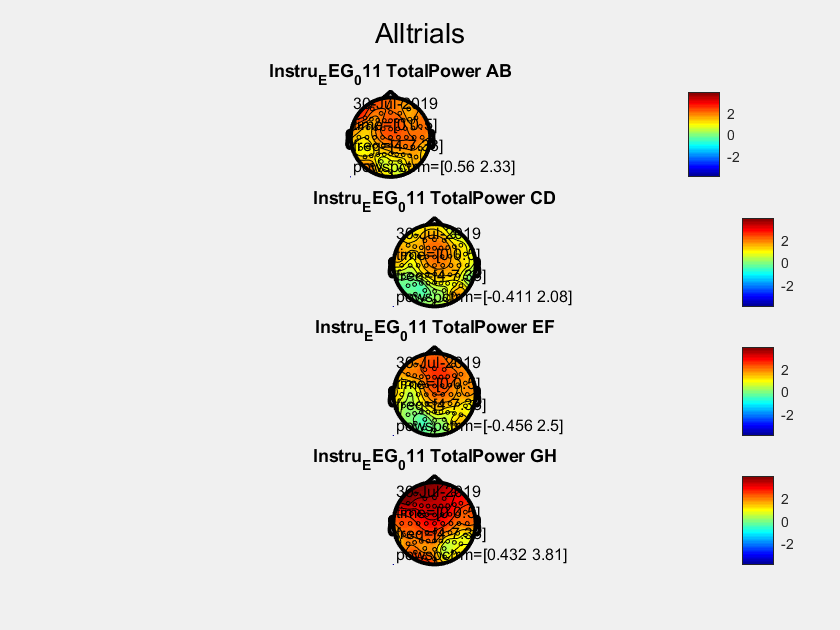

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


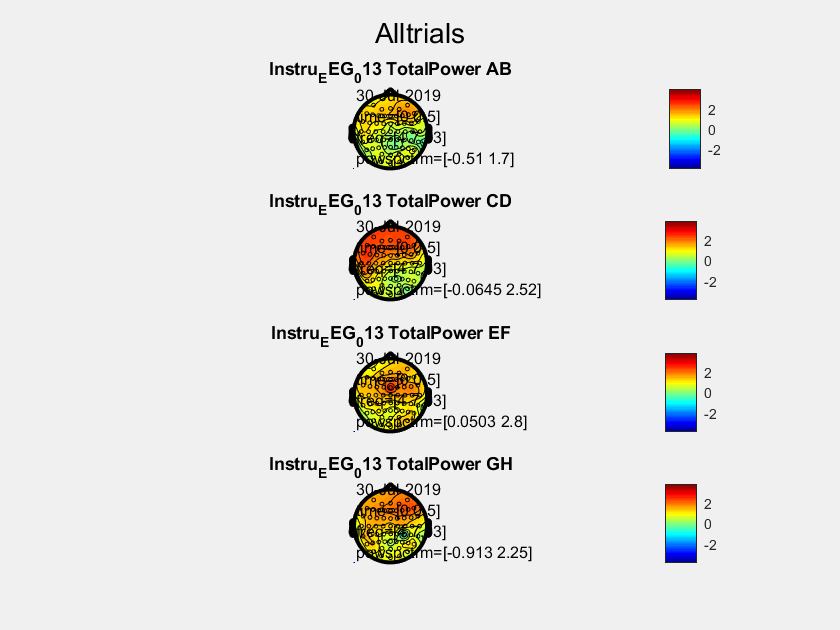

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


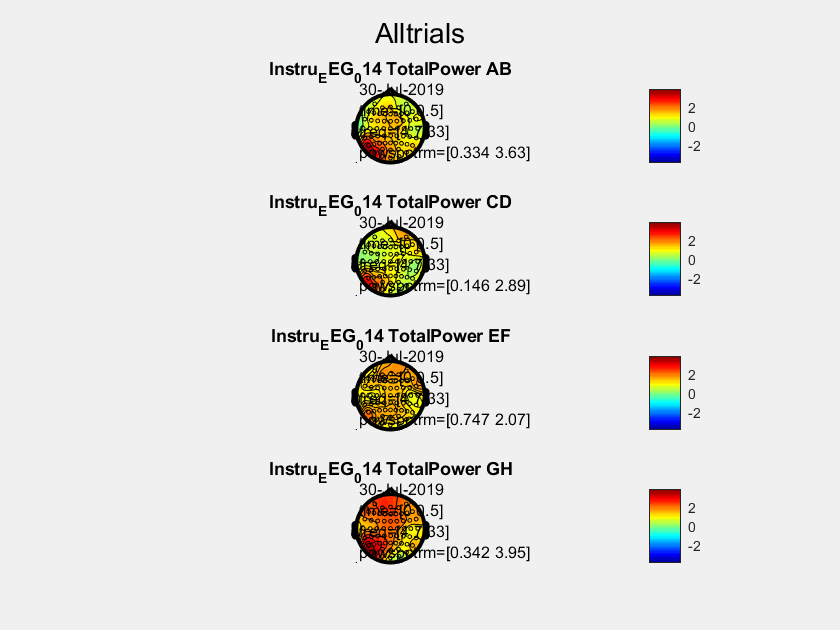

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


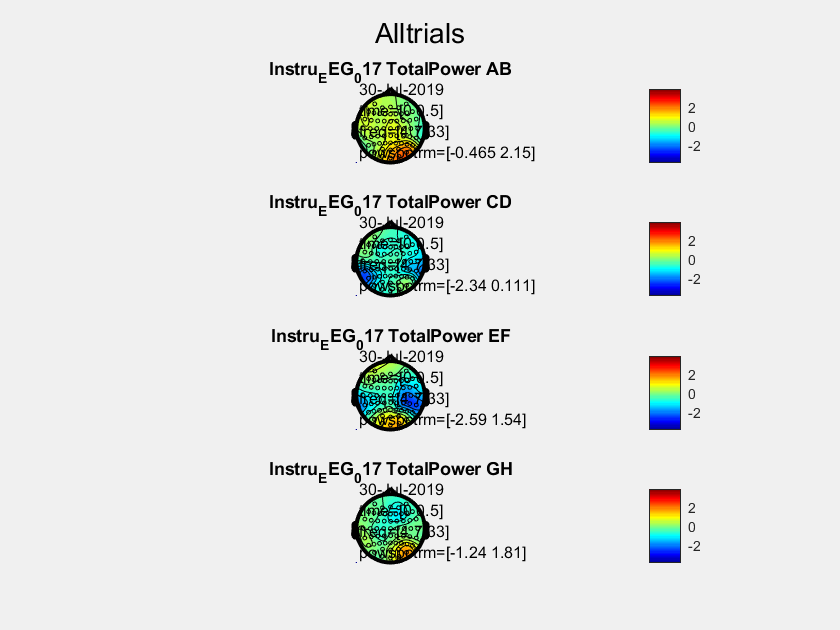

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


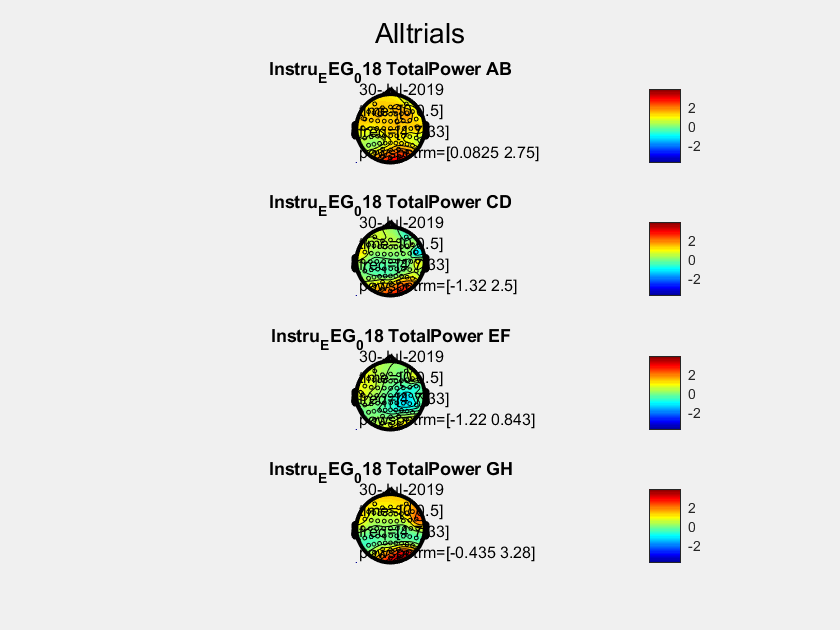

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


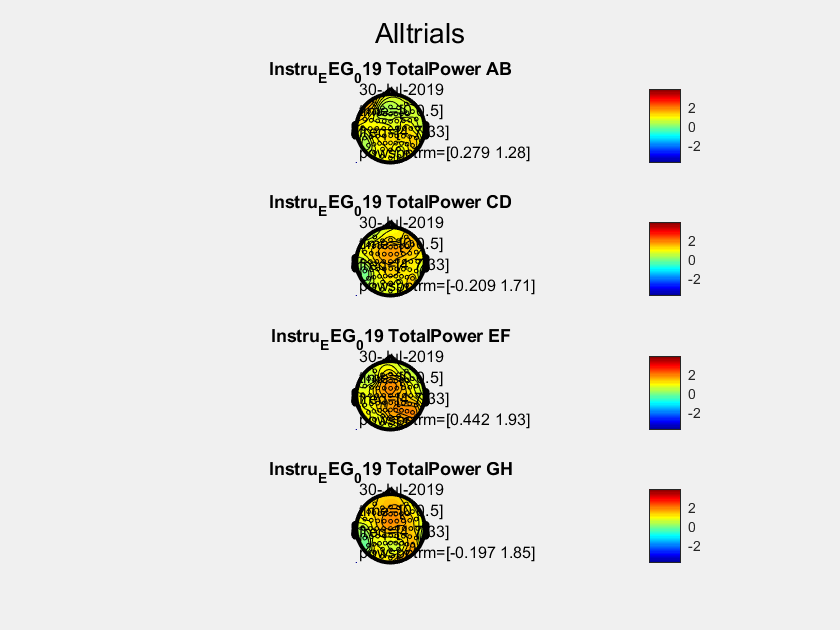

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


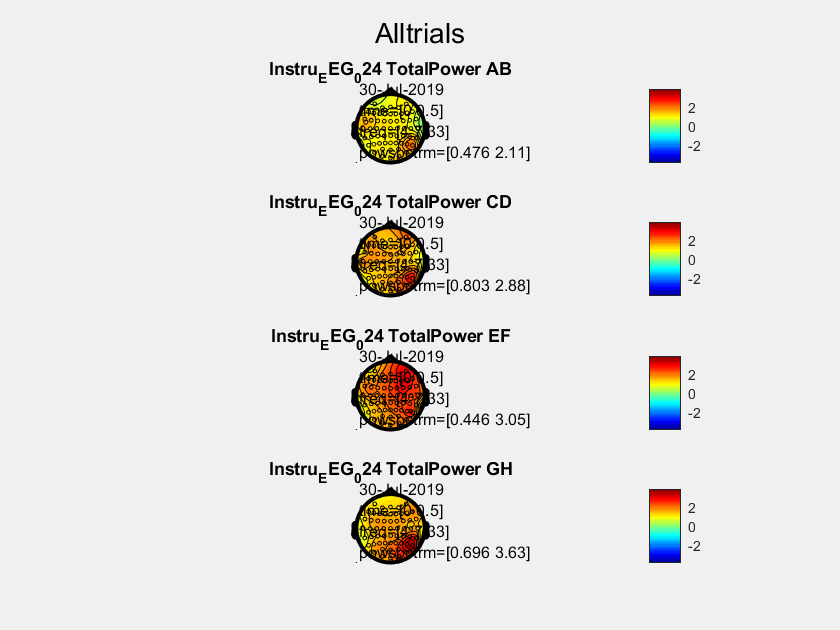

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


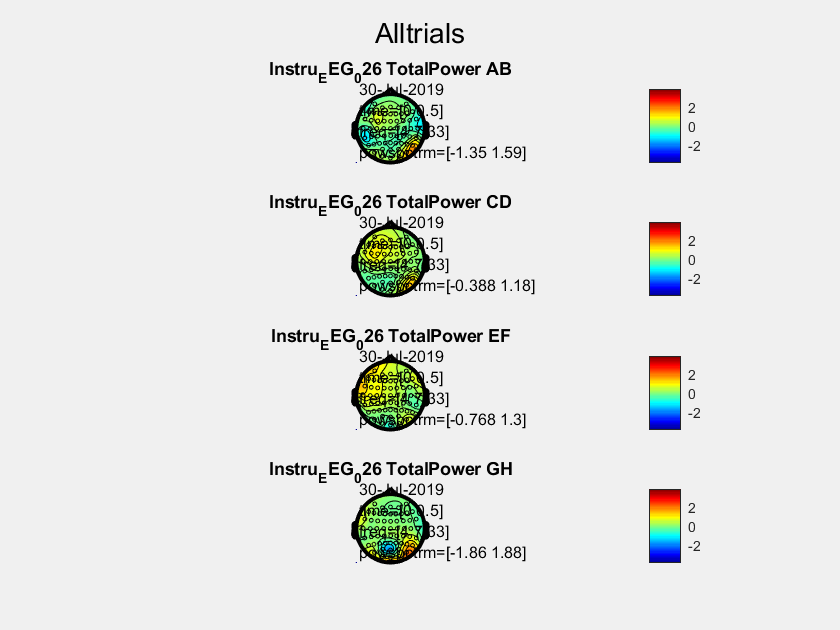

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


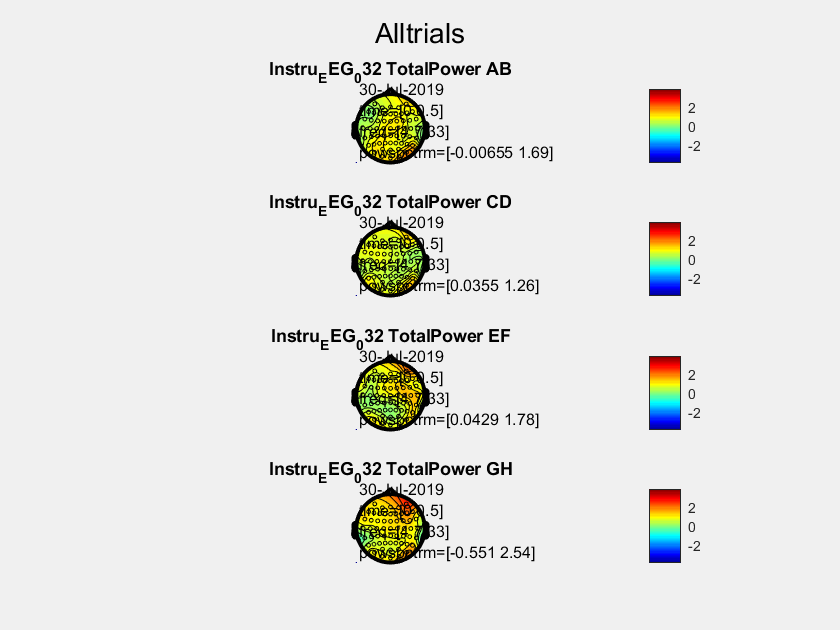

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


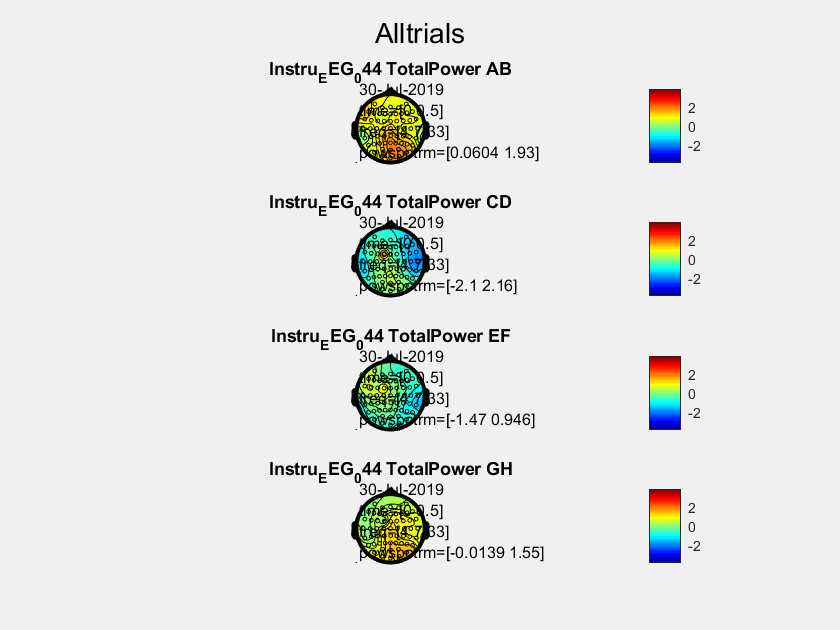

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


Deci_Backend(Deci);